# Examen Ejercicio 16

# Receptor Coherente

## **Demodulacion Coherente **DBLPS con Filtrado pasa bajas (Fase Cerrada de Costas)

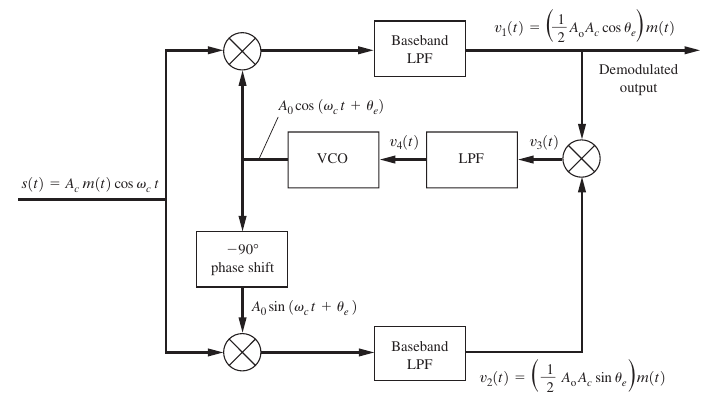

%   Señal de entrada   Señal DBLPS Normal
rt          =             sig_am_dsbsc;
%Local Oscilator
A_lo        =                       22; 
wc_lo       =            2*pi*freq_mod;
%vco         =   filt_tot_sig;
l_osc       =  A_lo .* cos(wc_lo+time);
%l_osc       = vco;
l_osc_90   =   A_lo .* sin(wc_lo+time);
%l_osc_90 algo que me derive 90° la señal entrante, por lo muentras esto
%//AQUI PUEDE IR EL FILTRO PARA LA SEÑAL DEL RECEPTOR

## Multiplicador Entrada Normal y Señal Retro Normal

if1_signal_am =        rt .* l_osc; %Multiplicador 1
if2_signal_am =     rt .* l_osc_90; %Multiplicador 2

## Filtrado LPF en frecuencia //ETAPA FILTRADO 91 COEFICIENTES LIMITADO A 5Hz

filt_sig1       =   lowpass(if1_signal_am, 4, freq_port );
filt_sig2       =   lowpass(if2_signal_am, 4, freq_port );
tot_sig         =                  filt_sig1 .* filt_sig2;
filt_tot_sig    =         lowpass(tot_sig, 4, freq_port );

## regresamos la señal al dominio del tiempo

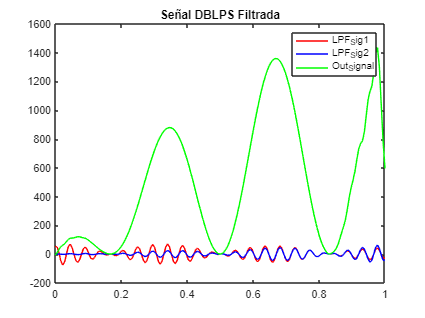

plot(time,filt_sig1,'r',time, filt_sig2,'b', time, filt_tot_sig, 'g' );
legend('LPF_Sig1','LPF_Sig2', 'Out_Signal');
title('Señal DBLPS Filtrada');

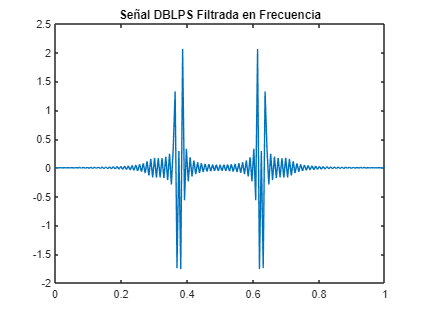

filt_sig_tot = real(ftot(filt_sig1));
plot(time,filt_sig_tot);
title('Señal DBLPS Filtrada en Frecuencia');

## Salida Demodulada es la Salida del Primer Filtro LPF

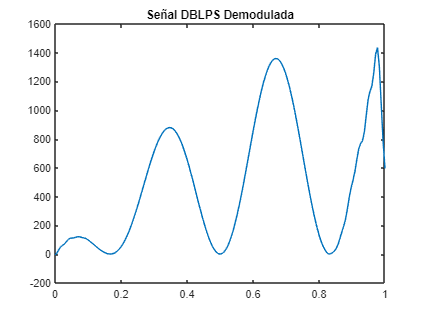

y_e = filt_tot_sig;
plot(time,y_e );
title('Señal DBLPS Demodulada');


%%  Etapa Filtro
%   91 coeficientes
%   Limitado 5Hz


## Generacion de ventana cuadrada 

Se define un tiempo de observacion de  segundos por ser $-\pi ,\pi$ el rango es $2\pi$

bound =[-5,5]; % 5hz range lenght
obs = 100 % 100 segundos 

obs = 100

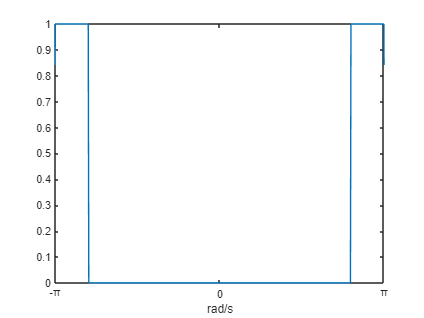

%Puntos de corte del filtro
cut_points =  [-pi -8*pi/10 8*pi/10 pi];

% tiempo de observacion 100s * 2pi = 625 muestras
space = bound(1):1/obs:bound(2)+1/100; 
%inicia señal de filtro en 0 
rad_space = zeros(1,length(space));

%parametros limite en la señal
%cut_freq_id se utilizara despues para el corte en tiempo tambien
cut_freq_id = []; 
%Counter for cutting points
cnt = 0;

%Iterate over all cutting points and when reach a pair of poins mod(cnt,2)
%assign them the frecuency square window. 

for section = cut_points % Ventana limits
   temp = find(space == interp1(space,space,section,'nearest'));%index in linespace
   cut_freq_id = [cut_freq_id temp]; % add index of limits
   cnt = cnt +1;
   if(mod(cnt,2) == 0) % Cnt is a pair of cutting values
       rad_space(cut_freq_id(cnt-1):cut_freq_id(cnt)) = 1;
   end
end

%Parametros de la grafica
plot(space,rad_space)
xlim([-pi pi])
xticks([-pi 0 pi 2*pi 3*pi])
xticklabels({'-\pi','0','\pi'})
xlabel('rad/s')

Converimos las ventanas de frecuencia a tiempo. 

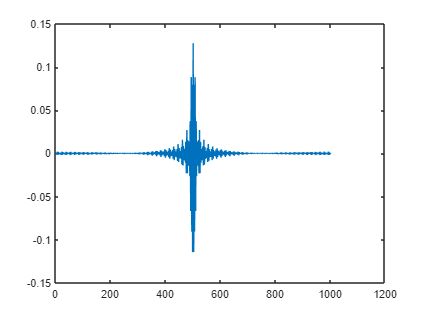

ventana_tiempo = real(ftot(rad_space));
plot(ventana_tiempo)

Generacion de ventanas en tiempo, con 91 coeficientes. Y una venta de hamming

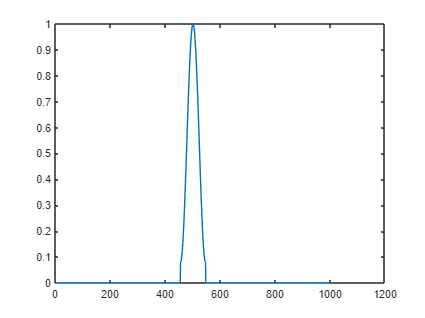

ventanacuad = zeros(1,length(space));
coeff       = 91;
middle      = (length(space))/2;
left        = int32((middle-coeff/2));
right       = int32((middle+coeff/2)); 
ventanacuad(left:right) = hamming(coeff+1)';
plot(ventanacuad)